clear 
clc
close all 

% Upload DATA_OPERATOR
load('data_operator.mat')

% run Name_script 
run geofencing.m

% Where are the operators? 
run beloging.m

run detector.m

This operator is always in this WS
This operator was never detected inside the j-th polygon
This operator was never detected inside the j-th polygon
This operator was never detected inside the j-th polygon
This operator was never detected inside the j-th polygon
This operator was never detected inside the j-th polygon
This operator was never again detected inside the j-th polygon
This operator was never again detected inside the j-th polygon
This operator was never again detected inside the j-th polygon
This operator was never again detected inside the j-th polygon
This operator was never again detected inside the j-th polygon
This operator was never again detected inside the j-th polygon
This operator was never again detected inside the j-th polygon
This operator was never again detected inside the j-th polygon
This operator was never again detected inside the j-th polygon
This operator was never again detected inside the j-th polygon
This operator was never again detected inside the 

# Workload of every operator in any station:

To calculate the workload percentage for each worker at every workstation, we initiate the process by extracting the time that each worker has allocated to various tasks and the total time spent by each worker.

To do that we use the table previusly made "events" and for each worker we compute the time spent a specific station. We calculated the overall working time for each worker by utilizing the events table and subtracting the time of the last event from that of the first one.

WorkloadOperatorInStat = zeros(5, 8);
%creating the zero matrix with dimension +2 for the sum of time and worker ID
for ws= 1:5  %for each workstation
    for i = 1:size(events{ws,1},1) %for each event/line in the event table
        for op= 1:6 % for each operator
            if (events{ws,1}{i,6} == op)
                WorkloadOperatorInStat(ws,op) = WorkloadOperatorInStat(ws,op)+events{ws,1}{i,5};
            end
            WorkloadOperatorInStat(ws,7) = seconds(events{ws,1}{size(events{ws,1},1),2}-events{ws,1}{1,1});
            WorkloadOperatorInStat(ws,8) = events{ws,2};

        end
    end
end
WorkloadOperatorInStat

WorkloadOperatorInStat =   892.9010         0         0         0         0         0  975.8510    1.0000
   34.2150    3.6490  511.2120    2.4270   11.3530    2.6890  918.5830    5.0000
  222.0090   34.7370   25.1250   22.6370  221.7550   50.7470  961.5500    4.0000
    0.5520  832.4140         0    1.4900   75.8940    0.9130  953.3790    2.0000
    2.0340    0.1630         0  817.4720         0    3.0110  848.4610    3.0000


Since there is no correspondence between the operator ID and the line in which its data is reported in the matrix, it is necessary to rearrange the matrix

orderedMatrix = sortrows(WorkloadOperatorInStat, size(WorkloadOperatorInStat, 2))

orderedMatrix =   892.9010         0         0         0         0         0  975.8510    1.0000
    0.5520  832.4140         0    1.4900   75.8940    0.9130  953.3790    2.0000
    2.0340    0.1630         0  817.4720         0    3.0110  848.4610    3.0000
  222.0090   34.7370   25.1250   22.6370  221.7550   50.7470  961.5500    4.0000
   34.2150    3.6490  511.2120    2.4270   11.3530    2.6890  918.5830    5.0000


The final matrix is structured such that orderedMatrix[op][ws] represents the total time that operator "op" spent at workstation "ws."

For displaying the percentage we firstly have to calculate for each worker the percentage of the time spent in a specific workstation on the total time. To do that we can just divide it by the total time for each workers calculated above. For sake of visualization a new matrix is computed with the corrent number of columns and rows

StatOpStat = zeros(5, 6);
for i=1:5
    for j=1:6
        StatOpStat(i,j)= (orderedMatrix(i,j)/orderedMatrix (i,7))*100;
    end
end
StatOpStat

StatOpStat =    91.4997         0         0         0         0         0
    0.0579   87.3120         0    0.1563    7.9605    0.0958
    0.2397    0.0192         0   96.3476         0    0.3549
   23.0887    3.6126    2.6130    2.3542   23.0622    5.2776
    3.7248    0.3972   55.6522    0.2642    1.2359    0.2927


To enhance visualization, we present the calculated data using a bar chart.

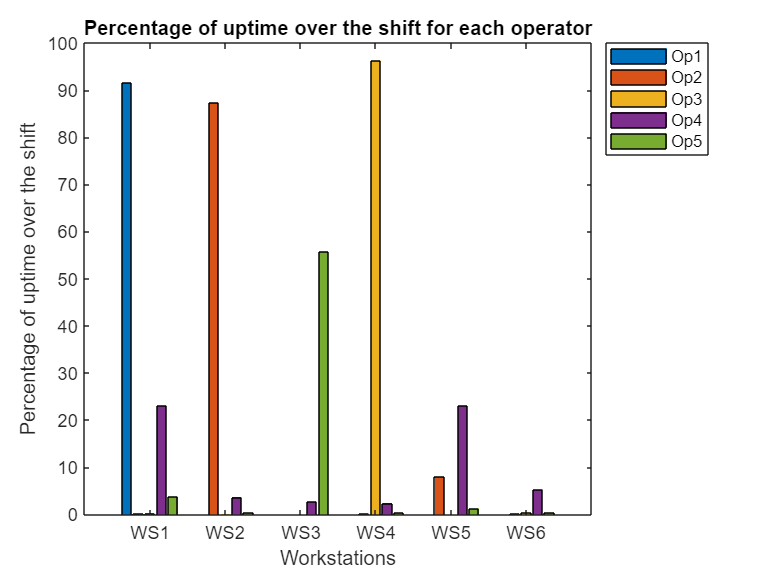

% Define the labels
resources = {'WS1', 'WS2', 'WS3', 'WS4', 'WS5', 'WS6'};
operators = {'Op1', 'Op2', 'Op3', 'Op4', 'Op5'};

% Create the bar chart with groups
figure;
bar(resources, StatOpStat', 'grouped');

% Customize the chart
title('Percentage of uptime over the shift for each operator');
xlabel('Workstations');
ylabel('Percentage of uptime over the shift');
legend(operators, 'Location', 'northeastoutside');

Examining the graph reveals that operators 1-2-3-5 predominantly allocate their uptime to a particular workstation, while operator 4 tends to distribute its workload across multiple stations.